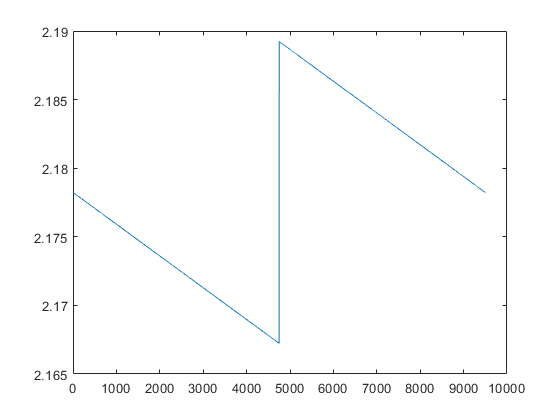

clc;clear;close all force;
E=210e9;
RA='225295';
d=digitosRA(RA);

[L,Izz,M0,b,h]=dados_problema(d);
P=M0/L;
Mz=momento(P,L,M0);
plot(Mz);

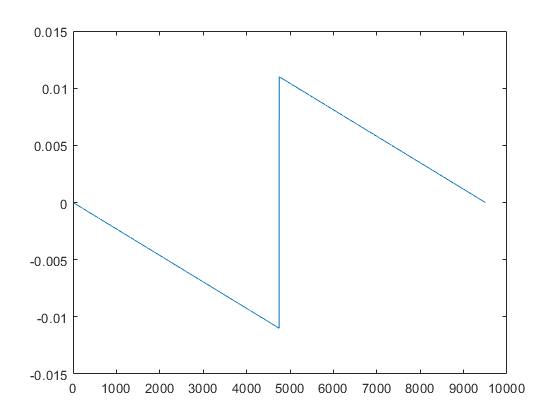

Mz=momento_sing(P,L,M0);
plot(Mz)

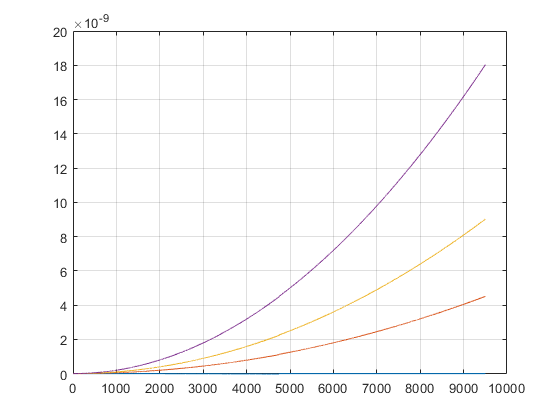

P=0;
vy=deflexao_normal(P,L,M0,E,Izz);
plot(vy);
hold on;
grid on;
P=M0/(2*L);
vy=deflexao_normal(P,L,M0,E,Izz);
plot(vy);
P=M0/L;
vy=deflexao_normal(P,L,M0,E,Izz);
plot(vy);
P=2*M0/L;
vy=deflexao_normal(P,L,M0,E,Izz);
plot(vy);
hold off;

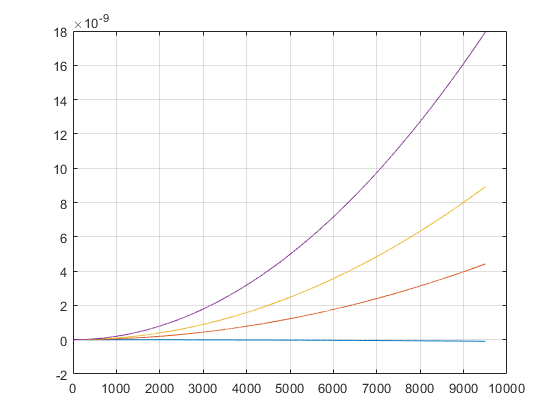

P=0;
vy=deflexao_sing(P,L,M0,E,Izz);
plot(vy);
hold on;
grid on;
P=M0/(2*L);
vy=deflexao_sing(P,L,M0,E,Izz);
plot(vy);
P=M0/L;
vy=deflexao_sing(P,L,M0,E,Izz);
plot(vy);
P=2*M0/L;
vy=deflexao_sing(P,L,M0,E,Izz);
plot(vy);
hold off;

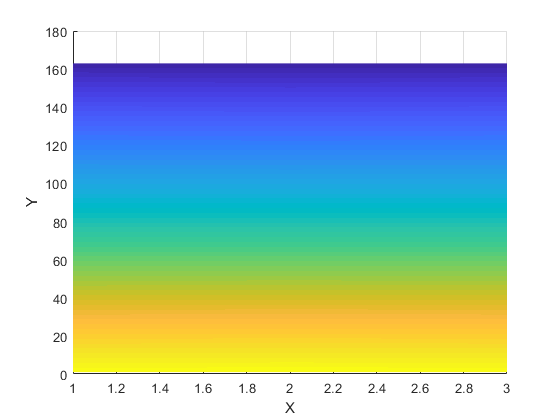

tensao_graph(L,M0,h,Izz)

function [d]=digitosRA(RA)
    d=[0 0 0 0 0 0];
    d(1)=RA(1)-48;
    d(2)=RA(2)-48;
    d(3)=RA(3)-48;
    d(4)=RA(4)-48;
    d(5)=RA(5)-48; 
    d(6)=RA(6)-48;
end

function [L,Izz,M0,b,h]=dados_problema(d)
    if(eq(d(5),0) || eq(d(6),0))  
        L=5;
    else
        L=10*d(5)+d(6);
    end
    b=10*d(3)+2*d(4);
    b=b*(0.01);
    h=3*b;
    M0=10*d(1)+d(2);
    M0=M0/1000;
    Izz=(b*(h^(3)))/12;
end

Agora vamos plotar o gráfico de Mz(x)

function y = sing(x,n) 
    %singularity function y = <x-a>^n 
    if n>=0 
        y = x.^n.*(x>=0); 
    else 
        y = 0*x; 
    end 
end

funcao do momento

function[Mz]=momento(P,L,M0)
   x=0:0.01:L;
   L=length(x);
   Mz=1:L;
   for i=1:L
       if(i<L/2)
           Mz(i)=P*L-M0-P*x(i);     
       else
            Mz(i)=P*(L-x(i));
       end
   end
end

funcao usando sing

function[Mz]=momento_sing(P,L,M0)
   x=0:0.01:L;
   Mz=1:length(x);
   for i=1:length(x)
       Mz(i)=P*L-M0-P*x(i)+M0*sing((x(i)-L/2),0);
   end
end

funcao deflex

function [vy]=deflexao_normal(P,L,M0,E,Izz)
   x=0:0.01:L;
   L=length(x);
   vy=1:L;
   for i=1:L
       if(i<L/2)
           vy(i)=((1/E*Izz)*(P*L-M0)*(x(i))^2/(2))-(1/E*Izz)*(P/6)*x(i)^3; 
       else
            vy(i)=((1/E*Izz)*(P*L-M0)*(x(i))^2/(2))-(1/E*Izz)*(P/6)*x(i)^3+(1/E*Izz)*(M0/2)*x(i)^2;
       end
   end   
end

funcao deflexao com sing

function [vy]=deflexao_sing(P,L,M0,E,Izz)
   x=0:0.01:L;
   L=length(x);
   vy=1:L;
   for i=1:L
       vy(i)=((1/E*Izz)*(P*L-M0)*(x(i))^2/(2))-(1/E*Izz)*(P/6)*x(i)^3+(1/E*Izz)*(M0/2)*sing((x(i)-L/2),2);
   end
end

Funcao tensao

function []=tensao_graph(M0,L,h,Izz)
    P=M0/L;
    x=0:0.01:L;
    x=1:length(L);
    y=-(h/2):0.01:h/2;
    Mzz=momento(P,L,M0);
    [X,Y]=meshgrid(Mzz,y);
    T=-X.*Y/Izz;
    surf(T);
    shading interp;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view(2);
end

#############PARTE 2#################

usar: fzero com vy

#############PARTE 23#################

usar: fminbnd com vy